# **3. FIR derivative filters**

## 3.1. FIR derivative filter properties (use the fvtool(b,a)) 

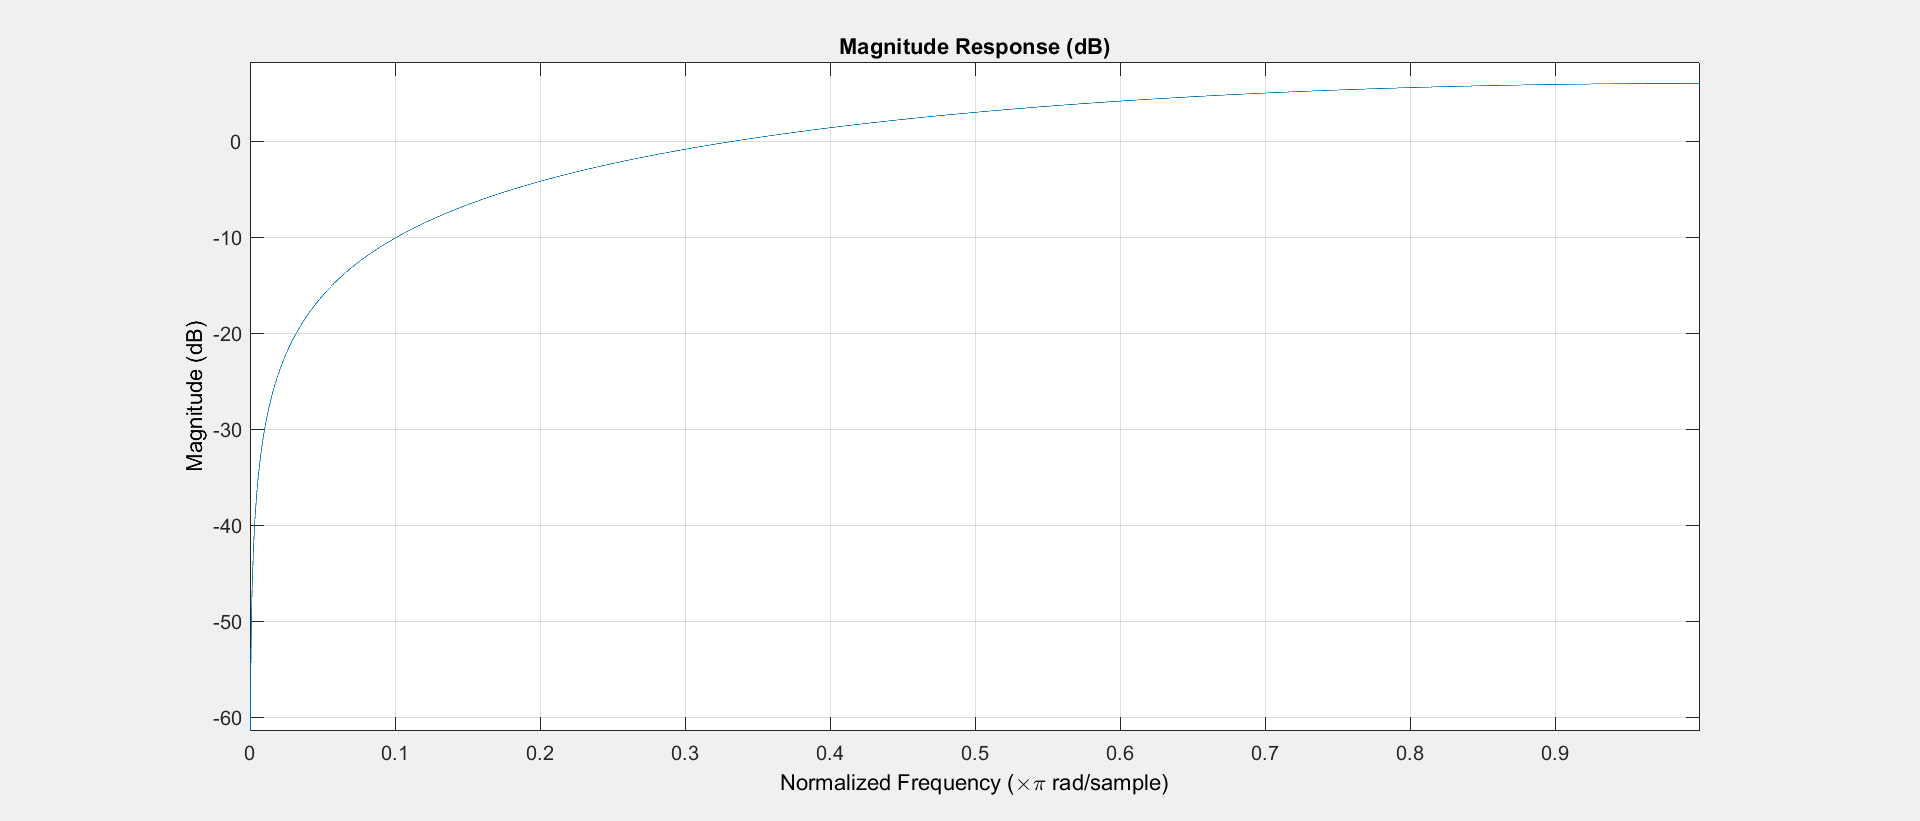

clear all; clc;

num1 = [1,-1];
den1 = 1;
num2 = [1,0,-1];
den2 = 1;
fvtool(num1,den1);

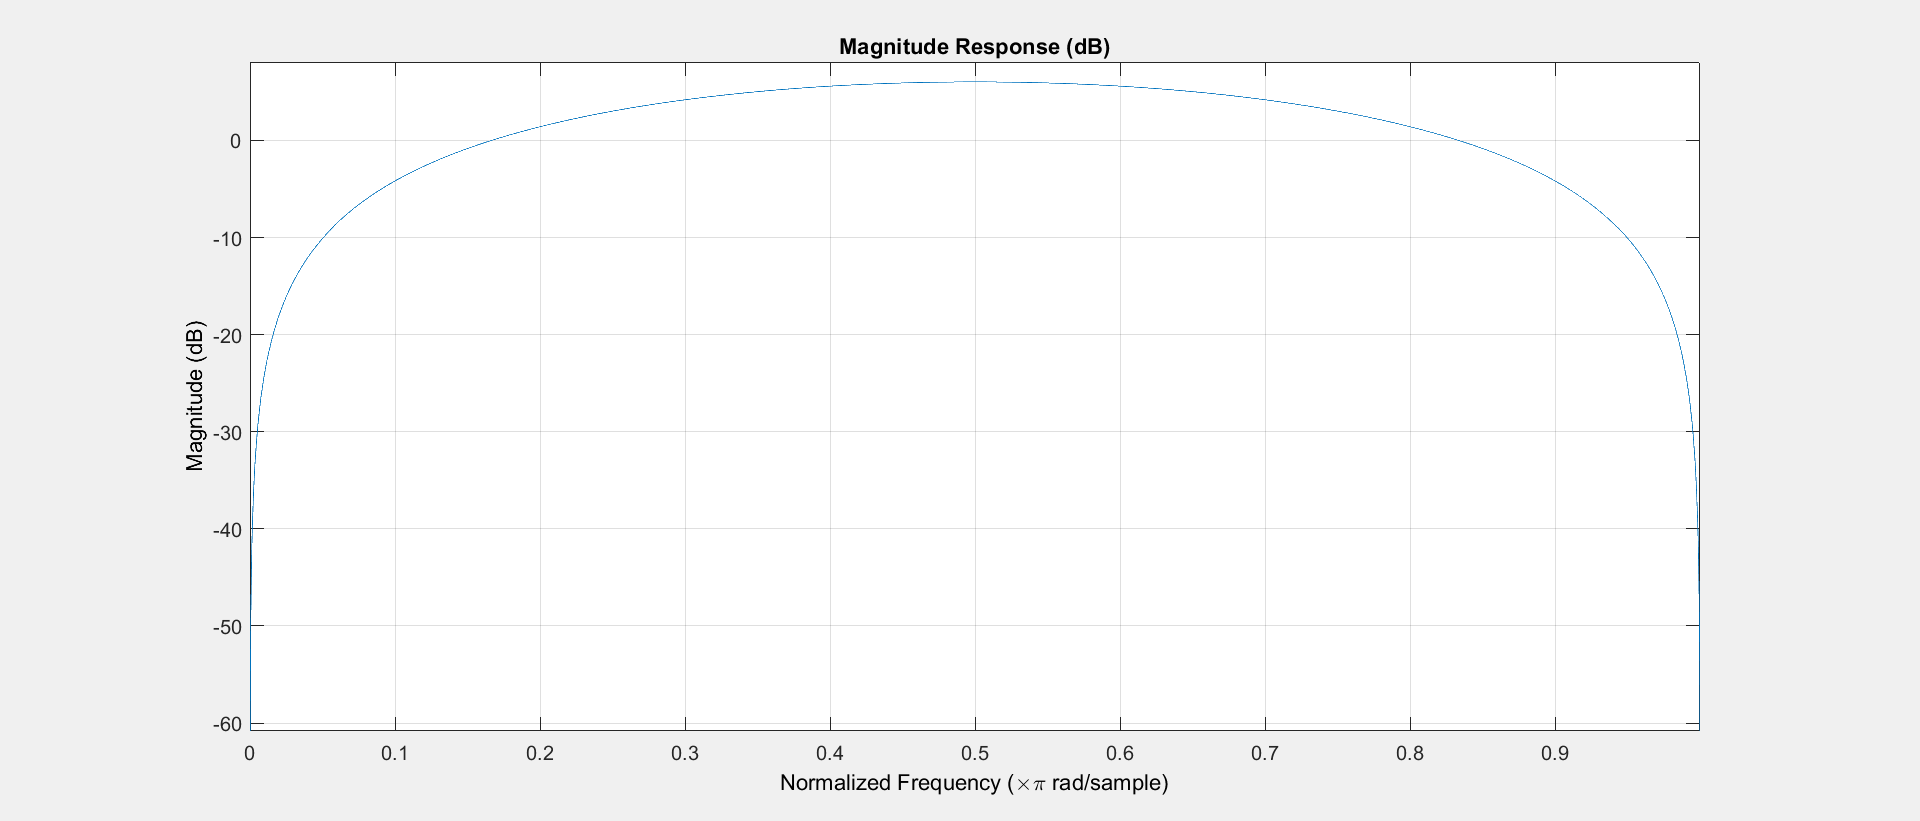

fvtool(num2,den2);

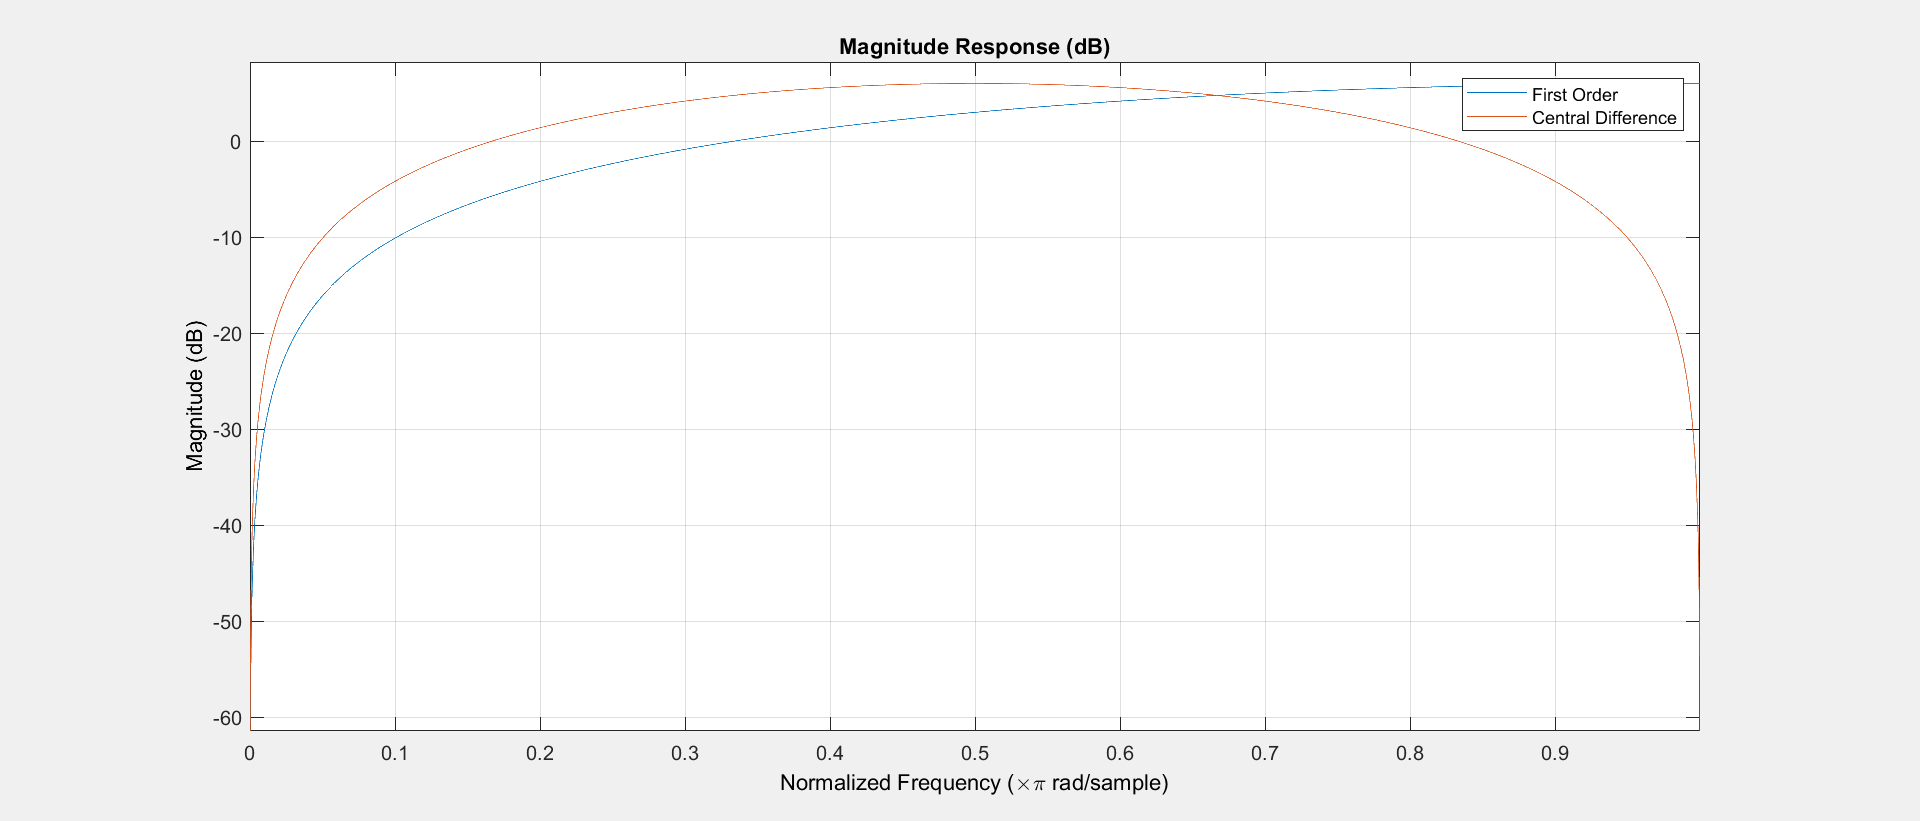

fvtool(num1 ,den1,num2 ,den2);
legend('First Order','Central Difference');

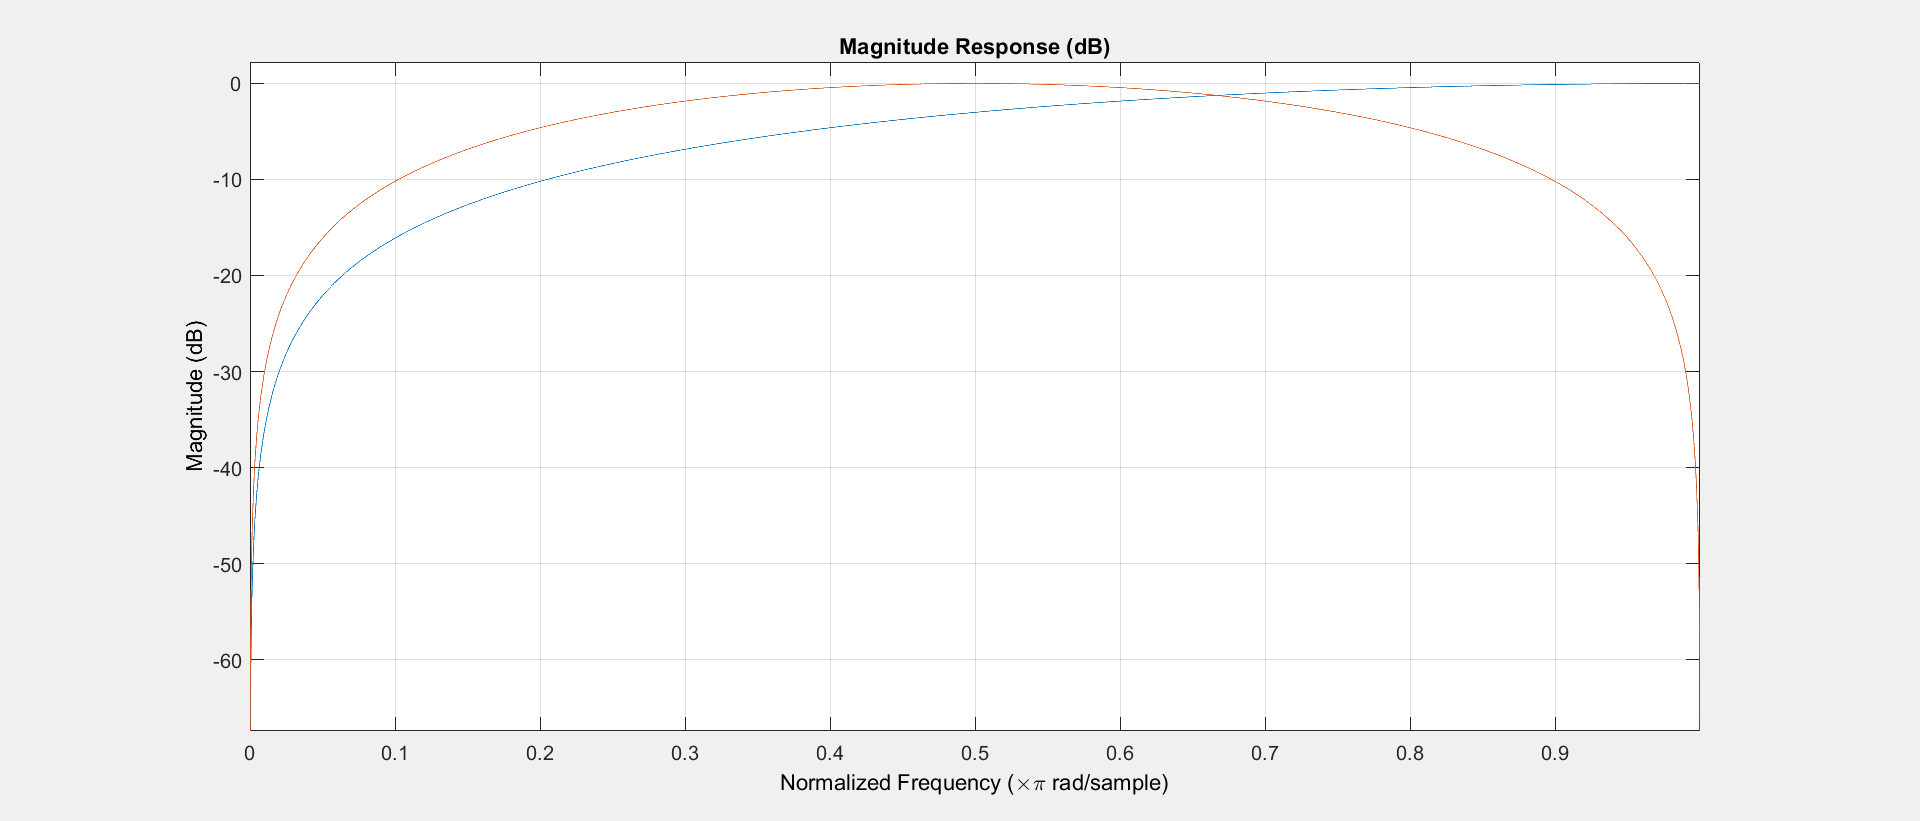

G1 = 0.5;
G2 = 0.5;
fvtool(num1*G1 ,den1,num2*G2 ,den2);

**3.2. FIR derivative filter application**

Load the data

load  ECG_rec.mat; 

fs=128;
t = (0 : length(ECG_rec) - 1)/fs;

%adding a Gaussian noise(10dB) and EMG noise to the signal 

nEMG = 2*sin((2*pi/4)*t) + 3*sin(((2*pi/2)*t) + (pi/4));
nECG = awgn(ECG_rec,10,'measured') + nEMG;

Plotting the noise addded ECG

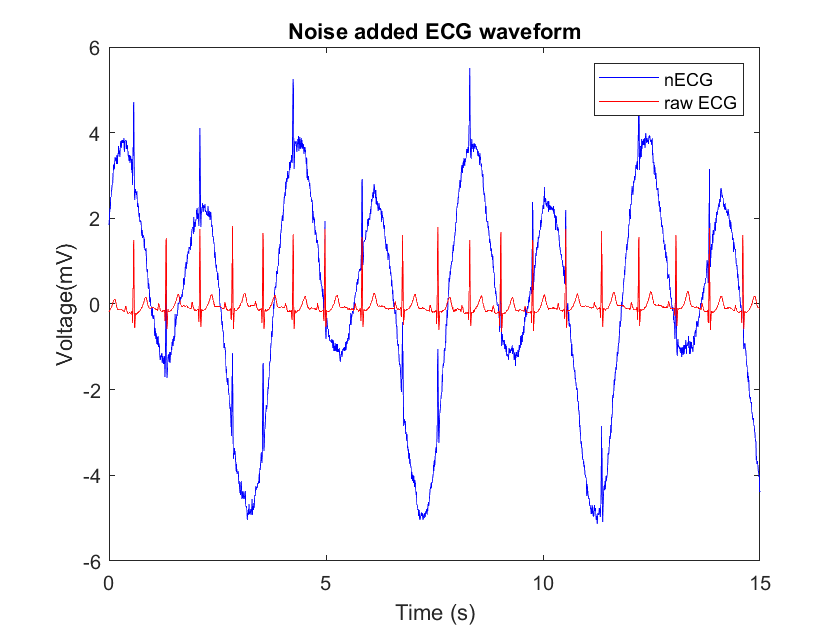

figure;
plot(t ,nECG , 'b' , t ,ECG_rec,'r' );
xlim([0,15]);
xlabel('Time (s)');
ylabel('Voltage(mV)');
title('Noise added ECG waveform');
legend('nECG','raw ECG');

Applying derivative filters

%first order derviative filter
y1 = filter(num1,den1,nECG);

%3 point central difference derviative filter
y2 = filter(num2,den2,nECG);

Plotting the filter applied signals

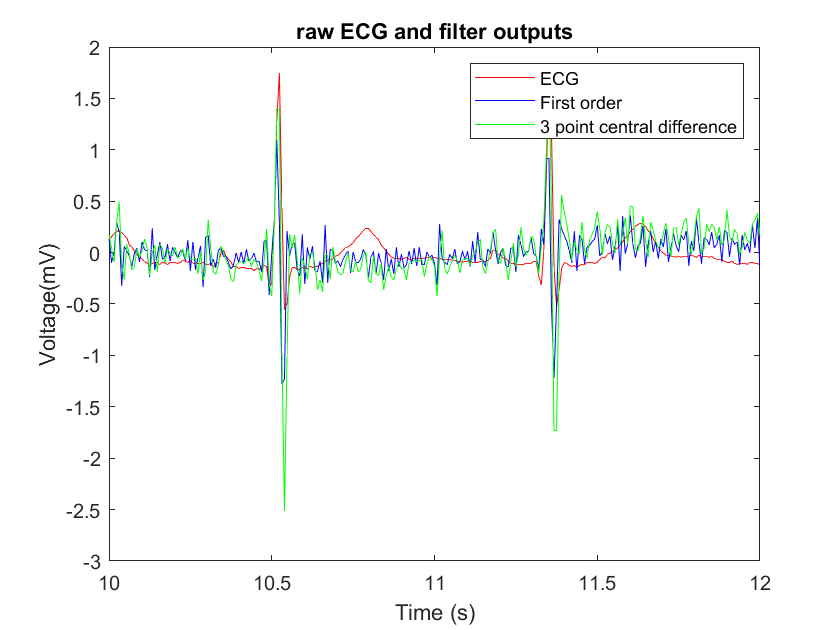

figure;
plot(t ,ECG_rec ,'r',t ,y1 ,'b',t,y2,'g');
xlim([10,12]);
xlabel('Time (s)');
ylabel('Voltage(mV)');
title('raw ECG and filter outputs');
legend('ECG', 'First order','3 point central difference');